# Chapter 1, Section 2 (Part 1)

In this activity we will introduce Gaussian Elimination and Back Substitution, methods used to solve systems of linear equations. Let's start with an example.

# Example #1:

Solve the following system for $x$, $y$, and $z$.


$$\begin{array}{rcl}
x+y+z&=&6\\
2x-y+z&=&3\\
3x+2y-z&=&4
\end{array}$$


**Solution: **The first step is to set up an augmented matrix for the system.


$$\pmatrix{1 & 1 & 1 & 6\cr 2 & -1 & 1 & 3\cr 3 & 2 & -1 & 4}$$


Now, let's enter this matrix in Matlab. We can use commas to separate each element in a row, and a semicolon to start a new row.

A=sym([1,1,1,6;2,-1,1,3;3,2,-1,4])

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 6\\ 2 & -1 & 1 & 3\\ 3 & 2 & -1 & 4 \end{array}\right)$$

We can also use spaces to separate each element in a row, and a semicolon to start a new row.

A=sym([1 1 1 6;2 -1 1 3;3 2 -1 4])

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 6\\ 2 & -1 & 1 & 3\\ 3 & 2 & -1 & 4 \end{array}\right)$$

There are three operations that can be applied to the augmented matrix that will change the form of the augmented matrix, but the new form has the same solutions as the original augmented form.

**Elementary Row Operations: **

**1. Replace one row by the sum of itself and a multiple of another row.**

**2. Interchange two rows.**

**3. Multiply all entries in a row by a nonzero constant.**

We begin by highlighting what is known as the leading term (the leftmost nonzero entry in a nonzero row) in row one. 


$$\pmatrix{[1] & 1 & 1 & 6\cr 2 & -1 & 1 & 3\cr 3 & 2 & -1 & 4}$$


Next, we will perform these two tasks to zero out the entries below the highlighted leading term in row one.

- We replace row two by the sum of itself and -2 times row one.

- We replace row three by the sum of itself and -3 times row one.


$$\pmatrix{[1] & 1 & 1 & 6\cr 2 & -1 & 1 & 3\cr 3 & 2 & -1 & 4}\quad\matrix{~\cr R_2-2R_1\cr R_3-3R_1 }\qquad\longrightarrow\qquad\pmatrix{[1] & 1 & 1 & 6\cr 0 & -3 & -1 & -9\cr 0 & -1 & -4 & -14}$$


Now we will use Matlab to check these steps. The notation A(1,:) selects row one, every column, of matrix A.

A(1,:)

$$ans = \left(\begin{array}{cccc} 1 & 1 & 1 & 6 \end{array}\right)$$

Similarly, the notation A(2,:) selects row two, every column, of matrix A.

A(2,:)

$$ans = \left(\begin{array}{cccc} 2 & -1 & 1 & 3 \end{array}\right)$$

And the notation A(3,:) selects row three, every column, of matrix A.

A(3,:)

$$ans = \left(\begin{array}{cccc} 3 & 2 & -1 & 4 \end{array}\right)$$

Now, to check our work, we'll store each row of matrix A in the variables r1, r2, and r3. 

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);

Now, we'll perform our elementary row operations using Matlab. Recall that we replaced row two with $R_2-2R_1$ and row three with $R_3-3R_1$ but row one remained the same. Let's create a new matrix A with these results.

A=[r1;r2-2*r1;r3-3*r1]

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 6\\ 0 & -3 & -1 & -9\\ 0 & -1 & -4 & -14 \end{array}\right)$$

That's the same as our hand-calulations above, so we are correct thus far, so let's store our new rows in r1, r2, and r3.

r1=A(1,:)

$$r1 = \left(\begin{array}{cccc} 1 & 1 & 1 & 6 \end{array}\right)$$

r2=A(2,:)

$$r2 = \left(\begin{array}{cccc} 0 & -3 & -1 & -9 \end{array}\right)$$

r3=A(3,:)

$$r3 = \left(\begin{array}{cccc} 0 & -1 & -4 & -14 \end{array}\right)$$

Now we will highlight the leading entry in row two.


$$\pmatrix{1 & 1 & 1 & 6\cr 0 & [-3] & -1 & -9\cr 0 & -1 & -4 & -14}$$


Now we will zero out the entry under our leading term in row two by performing the following task. We replace row three by the sum of itself and -1/3 times row one.


$$\pmatrix{1 & 1 & 1 & 6\cr 0 & -3 & -1 & -9\cr 0 & -1 & -4 & -14}\quad\matrix{~\cr ~ \cr R_3-(1/3)R_2 }\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 1 & 6\cr 0 & -3 & -1 & -9\cr 0 & 0 & -11/3 & -11}$$


Now, we will check this step with Matlab. Row one and row two remain the same, but row three is replaced with $R_3-(1/3)R_2$.

A=[r1;r2;r3-(1/3)*r2]

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 6\\ 0 & -3 & -1 & -9\\ 0 & 0 & -\frac{11}{3} & -11 \end{array}\right)$$

Nice! That agrees with our hand calculations above. Note: This final form is called row echelon form.

**Row Echelon Form: A rectangular matrix is in row echelon form if it has the following three properties:**

**1. All nonzero rows are above any rows of all zeros.**

**2. Each leading entry of a row is in a column to the right of the leading entry of the row above it.**

**3. All entries in a column below a leading entry are zeros.**

The row echelon form, though not unique, has the same solutions as our original augmented matrix representing our system of equations.

# Back Substitution

The first step is to take our last matrix and write the system of linear equations that is represented by the row echelon form:


$$\begin{array}{c}
\pmatrix{1 & 1 & 1 & 6\cr 0 & -3 & -1 & -9\cr 
0 & 0 & -11/3 & -11}
\end{array}$$


The system represented by this row echelon form is:


$$\begin{array}{rcl}
x+y+z&=&6\\
-3y-z&=&-9\\
-\frac{11}{3}z&=&-11
\end{array}$$


The process that we will use to solve this system is called "Back Substitution" because we begin with the last equation, solve it for $z$, substitute the result into the equation above it and solve for $y$, then substitute both results into the top equation and solve for $x$. Following this process, we first solve the last equation for $z$.


$$\begin{array}{rcl}
-\frac{11}{3}z&=&-11\\
z&=&3
\end{array}$$


Now we substitute $z=3$ into the second equation and solve for $y$.


$$\begin{array}{rcl}
-3y-z&=&-9\\
-3y-3&=&-9\\
-3y&=&-6\\
y&=&2
\end{array}$$


See how we are going "backwards?" Now we substitute $y=2$ and $z=3$ into the first equation and solve for $x$.


$$\begin{array}{rcl}
x+y+z&=&6\\
x+2+3&=&6\\
x&=&1
\end{array}$$


Therefore, the solution is:


$$(x,y,z)=(1,2,3)$$


Let's use Matlab's **solve** command (a command in the Symbolic Toolbox of Matlab) to check our solution. Recall the original system.


$$\begin{array}{rcl}
x+y+z&=&6\\
2x-y+z&=&3\\
3x+2y-z&=&4
\end{array}$$


Using the symbolic toolbox's solve command, we enter each of our equations  (note the double equal signs on each equation) and solve for x, y, and z, storing our answers in the variables x, y, and z.

syms x y z clear
[x,y,z]=solve(x+y+z==6,2*x-y+z==3,3*x+2*y-z==4,[x,y,z])

$$x = 1$$

$$y = 2$$

$$z = 3$$

That's the same as our hand-calculated answer above.

# Visualizing Our Answers

If we had a system of two equations in two unknowns, such as


$$\begin{array}{rcl}
x+y&=&1\\
x-y&=&3
\end{array}$$


it is easy to see that $(x,y)=(2,-1)$ is a solution (check it). As you learned in earlier algebra classes, these two equations represent two lines intersecting at the point $(2,-1)$. Because $x=2$, we will plot these equations over the interval $[-1,5]$, using the Symbolic Toolbox's fplot command. * Matlab's hold on command allows us to add a second graph to our image. Adding a hold off turns off the hold.*

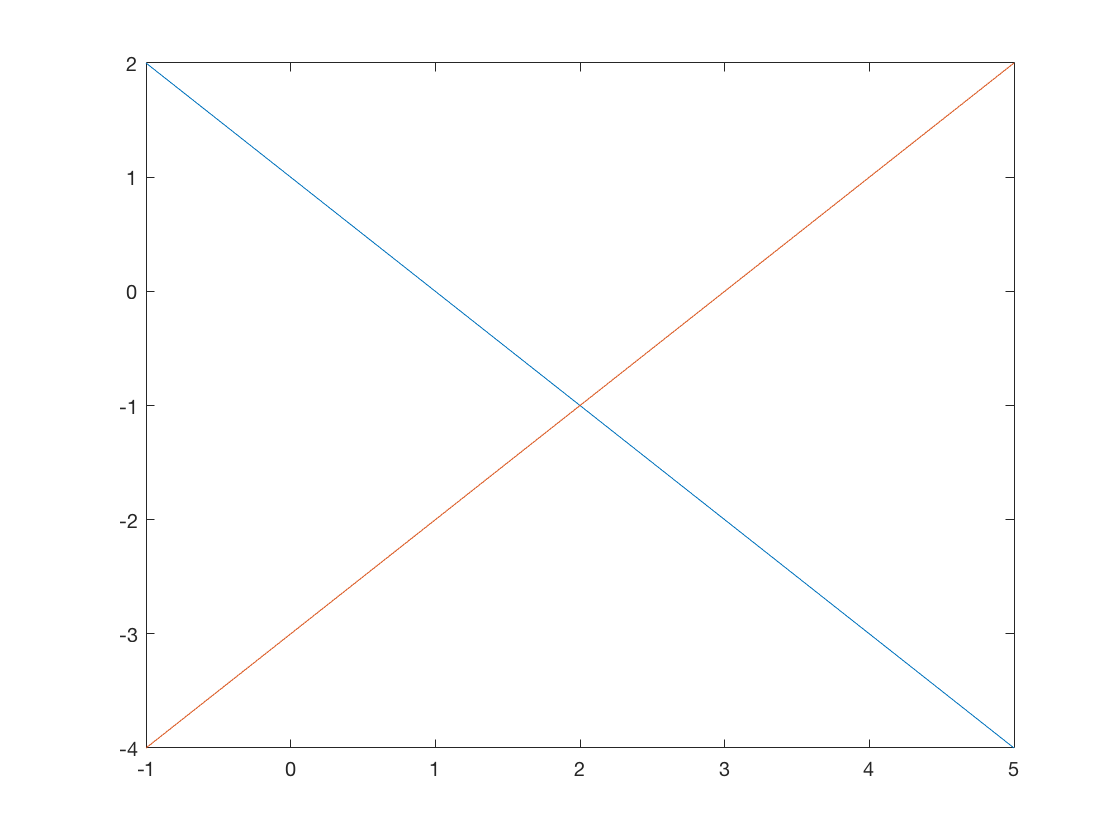

syms x clear
fplot(1-x,[-1,5])
hold on
fplot(x-3,[-1,5])
hold off

It certainly appears that the point of intersection is $(2,-1)$, but we can add some more code to prettify our image.

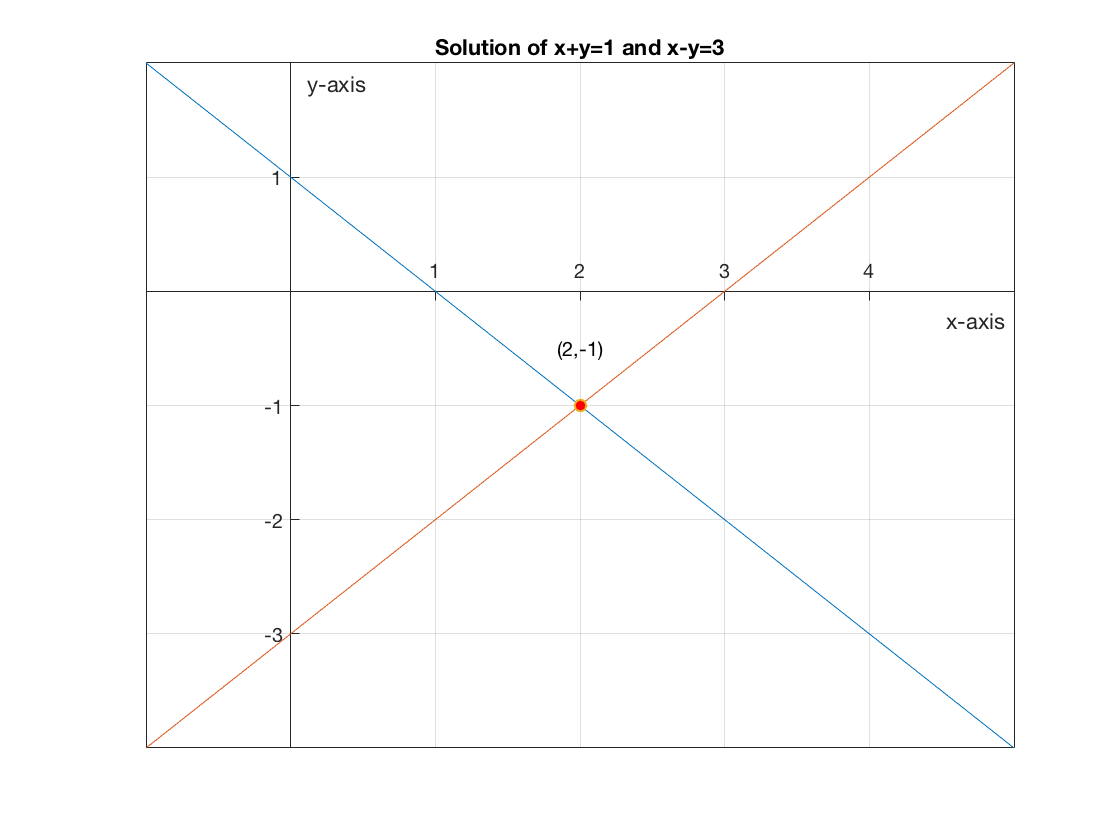

syms x clear
fplot(1-x,[-1,5]),hold on
fplot(x-3,[-1,5])
plot(2,-1,'Marker','o','MarkerFaceColor','r')
text(2,-0.5,'(2,-1)','HorizontalAlignment','center')
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')
title('Solution of x+y=1 and x-y=3')
hold off

**Matlab's surf Command**

Now, what about our system of three equations in three unknowns? How can we visualize our answer? One of the most important commands to understand in Matlab is the **meshgrid** command, which allows us to draw surfaces, vector fields, direction fields, etc. The meshgrid command creates a grid of points. 

Before we use the meshgrid command, let's consider some introductory commands. The following command generates the numbers starting at -1 and increments by 1 until the final 1 is reached.

-1:1:1

ans =     -1     0     1


Let's increment by 0.5 and see what happens.

-1:0.5:1

ans =    -1.0000   -0.5000         0    0.5000    1.0000


Note that the numbers start at -1, increment by 0.5, and finish at 1. Now we can use the meshgrid command. Suppose we want a grid of pointson the xy-plane where both the x and y values vary from -1 to 1 by increments of 1.

[X,Y]=meshgrid(-1:1:1)

X =     -1     0     1
    -1     0     1
    -1     0     1


Y =     -1    -1    -1
     0     0     0
     1     1     1


Notice that we know have two matrices X and Y, each with three rows and three columns. Note that each row of matrix X is -1, 0, 1 and each column of matrix Y is -1, 0, 1.

If you think about putting the matrix Y on top of the matrix X, it would produce these points:


$$\begin{array}{c|c|c}
(-1,-1) & (0,-1) & (1,-1)\\
(-1,0) & (0,0) & (1,0)\\
(-1,1) & (0,1) & (1,1)
\end{array}$$


Let's plot these points to show some visual evidence.

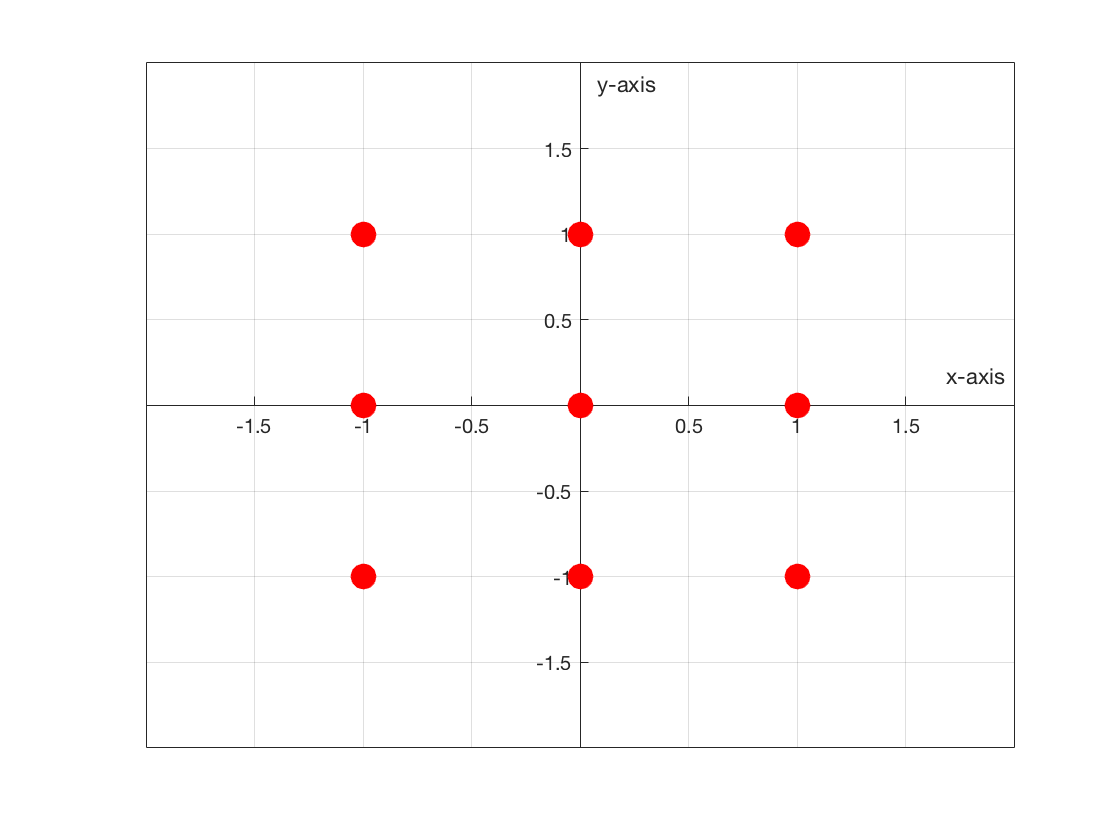

plot(X,Y,'ro','MarkerSize',12,'MarkerFaceColor','r')
grid on
xlabel('x-axis')
ylabel('y-axis')
axis([-2,2,-2,2])
ax=gca; % get the handle to the current axis
ax.XAxisLocation='origin';
ax.YAxisLocation='origin';

Let's plot a few more points.

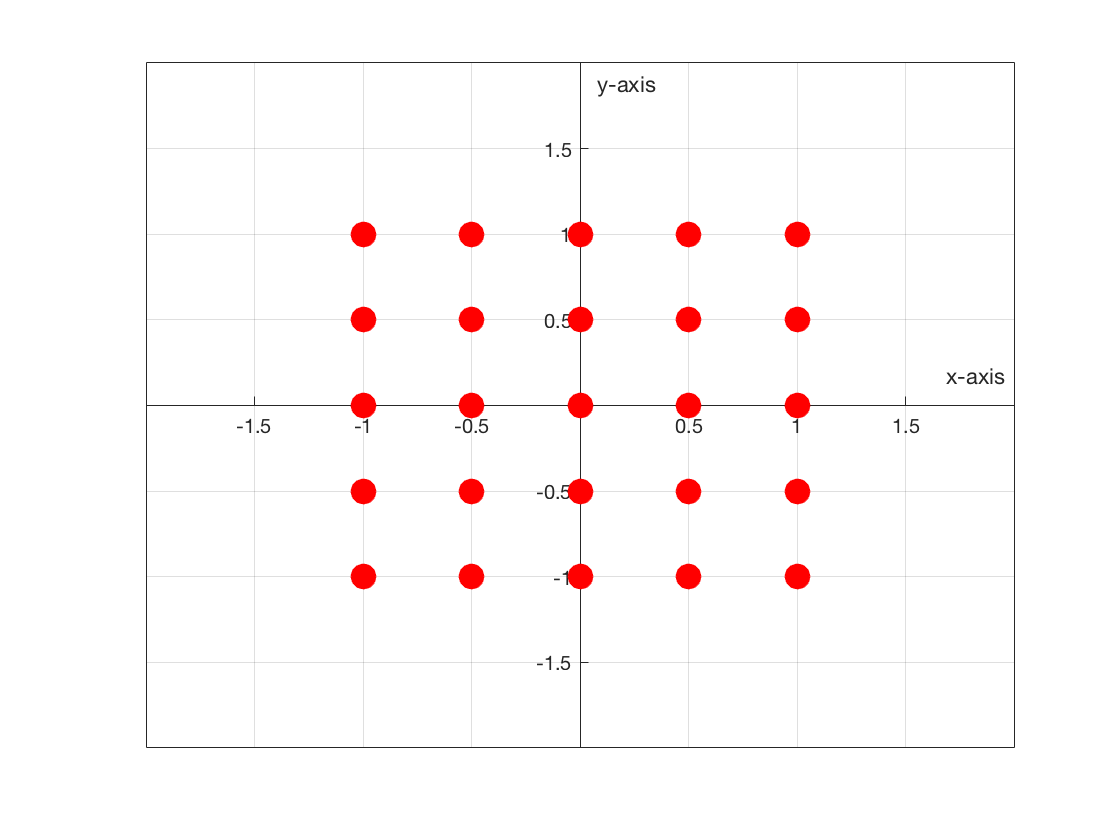

[X,Y]=meshgrid(-1:.5:1);
plot(X,Y,'ro','MarkerSize',12,'MarkerFaceColor','r')
grid on
xlabel('x-axis')
ylabel('y-axis')
axis([-2,2,-2,2])
ax=gca; % get the handle to the current axis
ax.XAxisLocation='origin';
ax.YAxisLocation='origin';

Now, if we have a function of $x$ and $y$, such as $z=f(x,y)$, we could plug each of these points into our function $z=f(x,y)$ to calculate the corresponding value of $z$. Then we could plot all of the points $(x,y,z)$ to see what the graph of $f$ looks like in three space. For example, suppose that $z=x+y$.

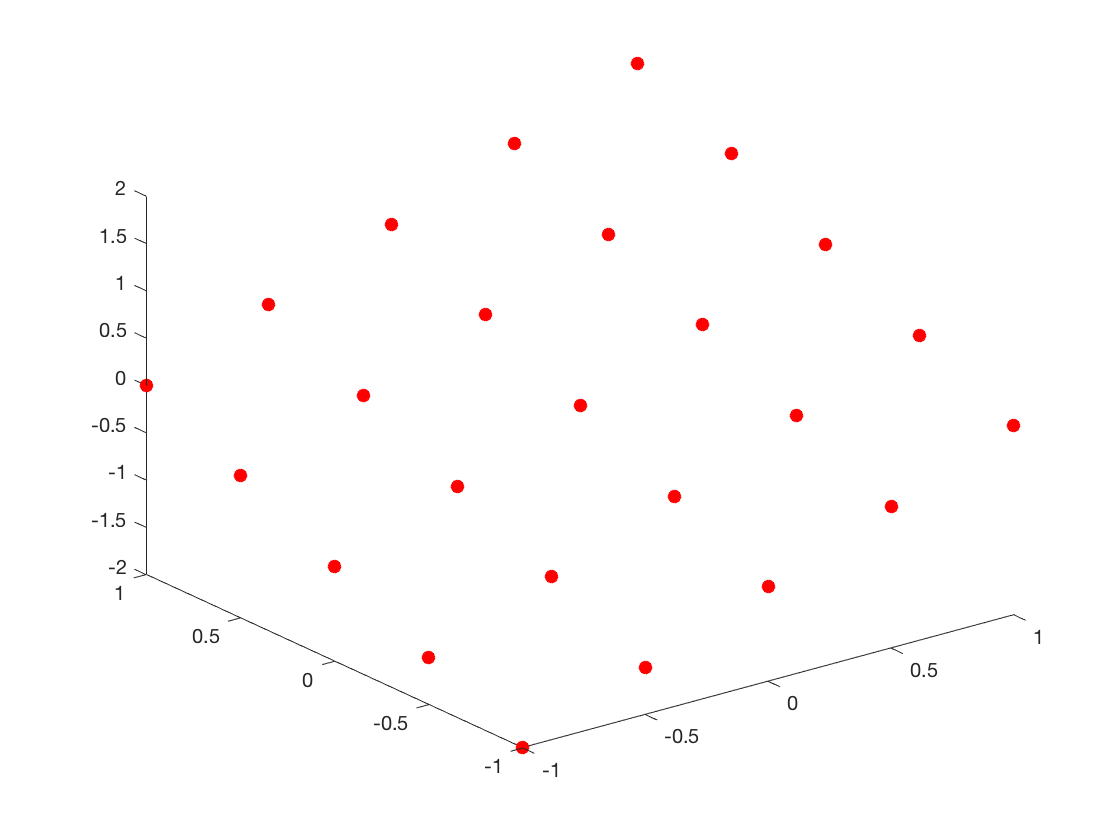

[X,Y]=meshgrid(-1:.5:1);
Z=X+Y;
plot3(X,Y,Z,'o','Color','r','MarkerFaceColor','r')

But let's use Matlab's **surf** command, which will do an estimation of other surface points inbetween our points.

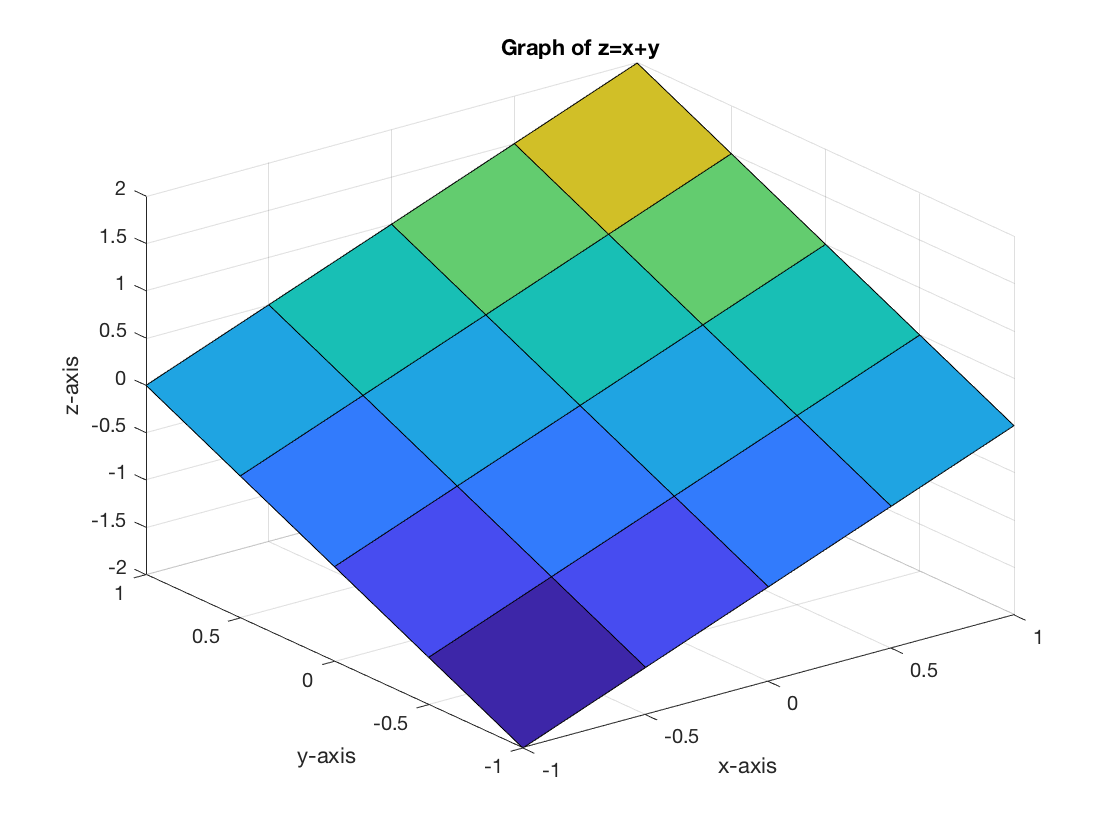

[X,Y]=meshgrid(-1:.5:1);
Z=X+Y;
surf(X,Y,Z)
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
title('Graph of z=x+y')

Matlab assigns a color to each rectangle in this image based on its height (the z-value), but we can choose our own face value for each rectangle.

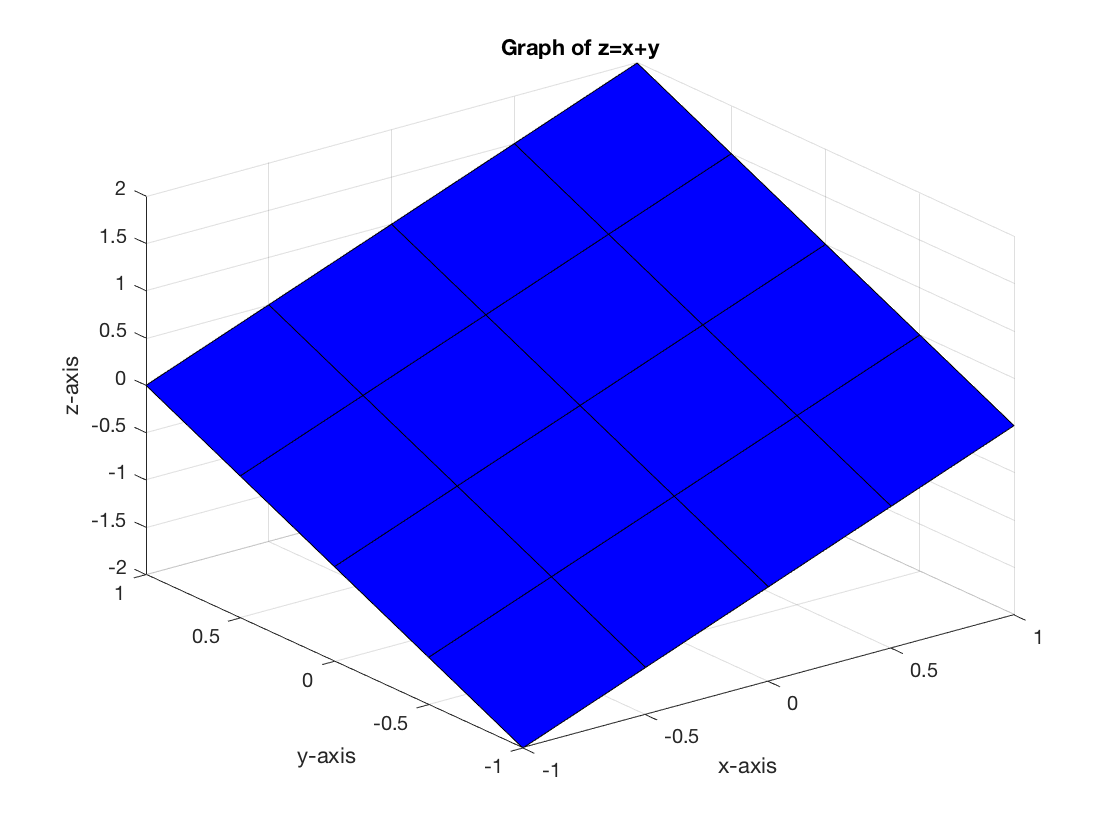

[X,Y]=meshgrid(-1:.5:1);
Z=X+Y;
surf(X,Y,Z,'FaceColor','blue')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
title('Graph of z=x+y')

# Visualizing the Answer to Our System

Recall that our system was


$$\begin{array}{rcl}
x+y+z&=&6\\
2x-y+z&=&3\\
3x+2y-z&=&4
\end{array}$$


and our solution was $(x,y,z)=(1,2,3)$. Now we checked our solution several ways, but can we visualize our solution? Let's solve each of our equations independently for $z$.


$$\begin{array}{rcl}
z&=&6-x-y\\
z&=&3-2x+y\\
z&=&3x+2y-4
\end{array}$$


Now, we will make a choice for our x and y values, based on our solution, which is $(x,y,z)=(1,2,3)$. Because $x$ equals 1, we'll go one unit to the left and right of 1, choosing the interval $[0,2]$ for our $x$-values. Matlab's linspace(a,b,n) gives n equally spaced points between and including a and b. For example,

x=linspace(0,2,5)

x =          0    0.5000    1.0000    1.5000    2.0000


returns five equally spaced points between and including 0 and 2. Let's choose 20 equally spaced points between 0 and 2.

x=linspace(0,2,20);

We added a semicolon to suppress the output. Because $y=2$, we'll go one unit to the left and right of 2, choosing the interval $[1,3]$ for our $y$-values. Again, let's generate 20 equally space values between 1 and 3.

y=linspace(1,3,20);

Now we can use the meshgrid command to obtain a grid of points $\{(x,y): 0\le x\le 2\text{ and } 1\le y\le 3\}$. Again, we'll suppress the output, but we can erase the semicolon if we'd like to see the output. Now, let's draw the graph of our first equation, which is $z=6-x-y$ over the interval $\{(x,y): 0\le x\le 2\text{ and } 1\le y\le 3\}$.

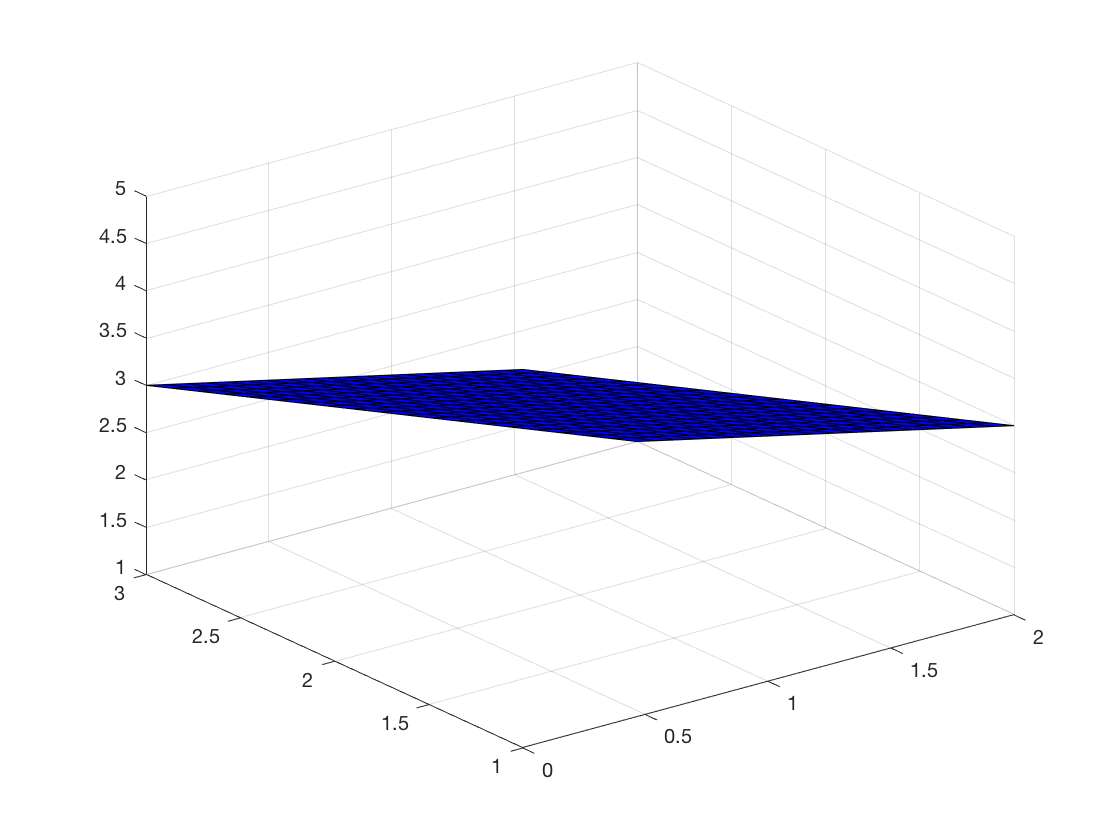

x=linspace(0,2,20);
y=linspace(1,3,20);
[X,Y]=meshgrid(x,y);
Z=6-X-Y;
surf(X,Y,Z,'FaceColor','blue')

Now, let's add the graph of our second equation $z=3-2x+y$ to our image. We use the hold on command so that our first graph is not erased.

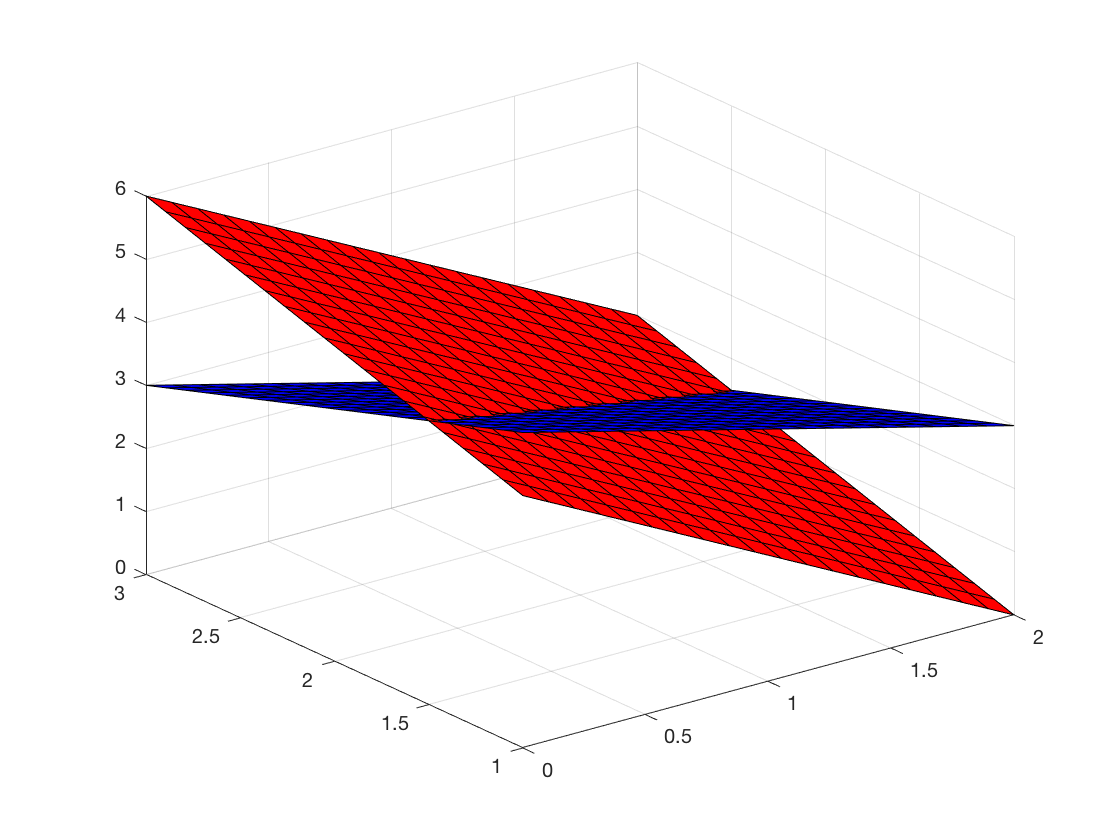

x=linspace(0,2,20);
y=linspace(1,3,20);
[X,Y]=meshgrid(x,y);
Z=6-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=3-2*X+Y;
surf(X,Y,Z,'FaceColor','red')
hold off

The first two planes intersect in a line. Now, let's add the graph of our third equation to our image, $z=3x+2y-4$.

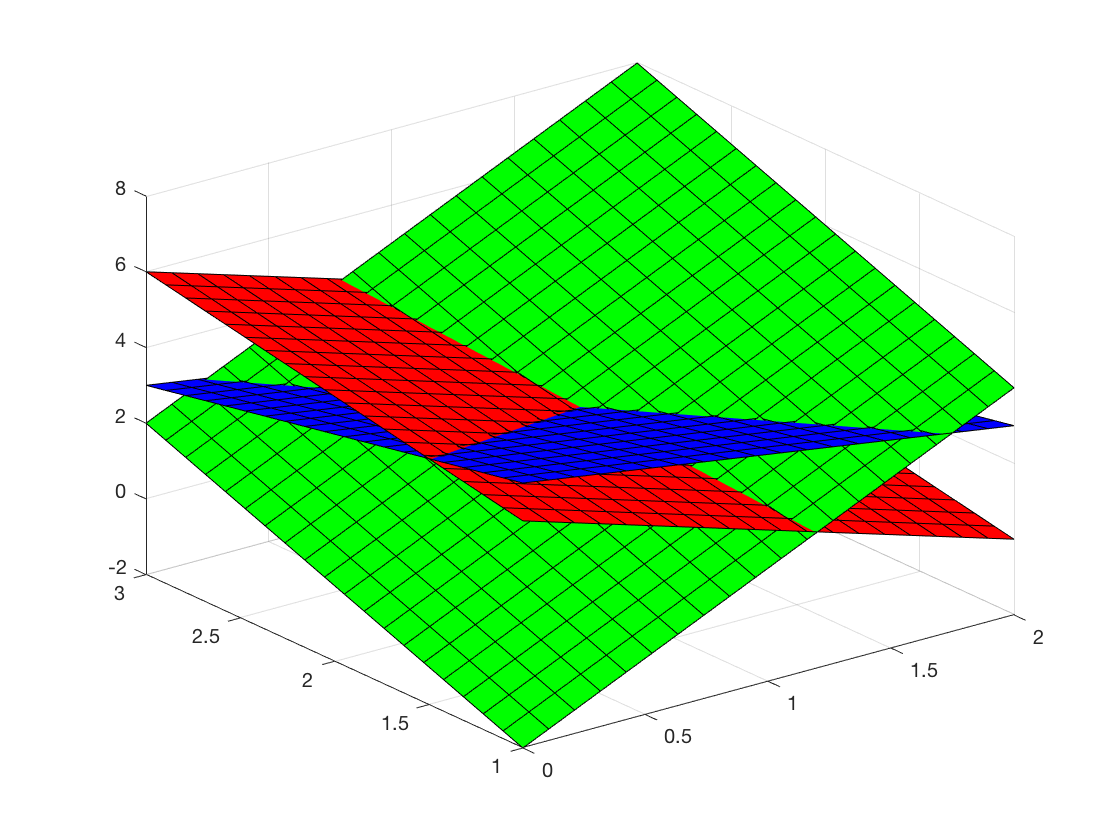

x=linspace(0,2,20);
y=linspace(1,3,20);
[X,Y]=meshgrid(x,y);
Z=6-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=3-2*X+Y;
surf(X,Y,Z,'FaceColor','red')
Z=3*X+2*Y-4;
surf(X,Y,Z,'FaceColor','green')
hold off

Now, it appears that the three planes intersect at a single point, but is it our point $(1,2,3)$? Let's add the point $(1,2,3)$ to our image.

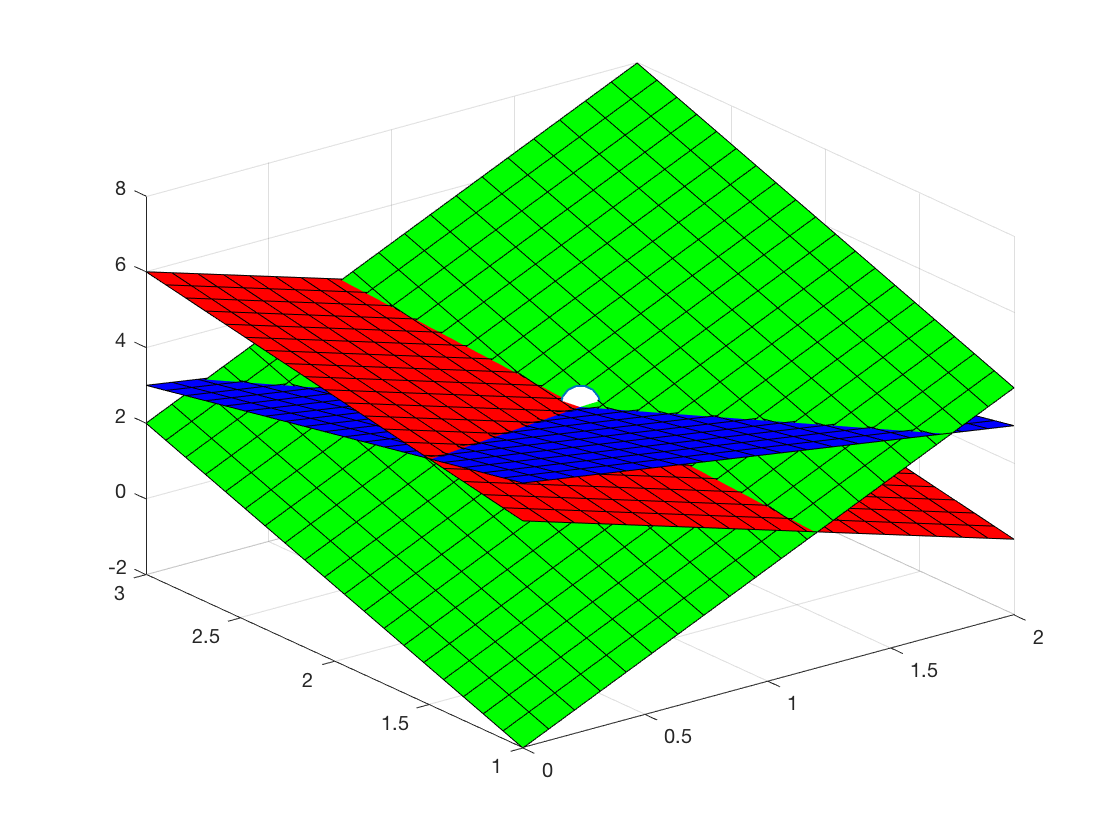

x=linspace(0,2,20);
y=linspace(1,3,20);
[X,Y]=meshgrid(x,y);
Z=6-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=3-2*X+Y;
surf(X,Y,Z,'FaceColor','red')
Z=3*X+2*Y-4;
surf(X,Y,Z,'FaceColor','green')
plot3(1,2,3,'o','MarkerSize',20,'MarkerFaceColor','white')
hold off

This is clear visual evidence that the point $(1,2,3)$ lies on all three planes, so our answer is correct. We'll leave it to our readers to substitute $x=1$, $y=2$ and $z=3$ into each of the original equation to see that it satisfies all three equations.